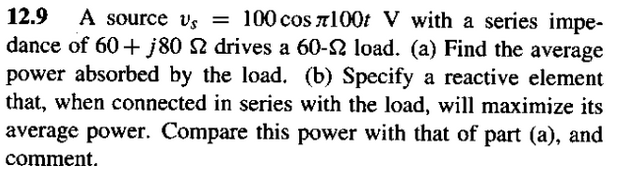

clc, clear, close all

vf = 100;
w = pi*100;
f = w/(2*pi);

zs = 60 + j*80;
r = 60;


**a)** calculamos la potencia activa

If = vf/(zs+r);
I_f = [abs(If)/sqrt(2) angle(If)*180/pi] %[A]

I_f =       0.49029       -33.69


p = (vf/sqrt(2))*(abs(If)/sqrt(2))*cos(angle(If)) %potencia activa consumida por el circuito [W]

p =        28.846


pr = ((abs(If)/sqrt(2))^2)*r %potencia consumida por la carga [W]

pr =        14.423


verificamos en el simulador

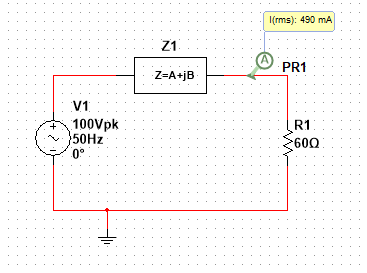

**b)** 

tenemos una funete de tension en serie con una impedancia, para que haya maxima transferencia de potencia en la carga, esta debe ser igual al conjugado de la impedancia thevenin, o la que esta en serie con la funete:

z_load = conj(zs)

z_load =            60 -         80i


If = vf/(zs+z_load)

If =       0.83333


If_rms = If/sqrt(2) 

If_rms =       0.58926


pzl = real(((abs(If)/sqrt(2))^2)*z_load) %potencia consumida por la carga para este caso

pzl =        20.833


verificamos en el simulador